# PRÁCTICA 1

clc % Borra la command window
clear % Limpia las variables del workspace
format short

## Objetivos

- Identificar y analizar la presencia de correlaciones positivas entre las variables de un conjunto de datos.

- Aprender a extraer características de imágenes utilizando técnicas de procesamiento de imágenes.

- Observar de manera experimental los efectos del procesamiento de datos, imágenes y señales.

- Familiarizarse con el proceso de limpieza y preprocesamiento de los datos.

- Aprender a generar señales sintéticas y visualizarlas para su análisis o procesamiento posterior.

## Introducción

### Preprocesamiento y limpieza de datos para el reconocimiento de patrones

El preprocesamiento de datos es una etapa fundamental en el reconocimiento de patrones, ya que garantiza la calidad y relevancia de los datos antes de su análisis. Este proceso incluye varias técnicas como limpieza, transformación, reducción y normalización de datos. La limpieza de datos implica la eliminación de valores atípicos, datos incompletos o inconsistentes, mientras que la transformación convierte los datos en un formato adecuado, como la codificación de variables categóricas o la aplicación de transformaciones matemáticas. La normalización y estandarización aseguran que los datos tengan una escala uniforme, lo cual es crucial para algoritmos que dependen de medidas de distancia. Además, en el caso de datos textuales o de imágenes, se aplican técnicas específicas como la tokenización o el filtrado de ruido. Un buen preprocesamiento no solo mejora la precisión de los modelos de reconocimiento de patrones, sino que también reduce el tiempo de procesamiento y evita problemas de sobreajuste.

En este proceso se aplican diferentes técnicas de análisis de datos que van desde la visión por computadora hasta el procesamiento de señales biomédicas. Las principales técnicas utilizadas en el preprocesamiento de datos son:

**Limpieza de datos: **Consiste en eliminar errores, valores atípicos y datos faltantes para asegurar la calidad de los datos antes de su uso en modelos de reconocimiento de patrones. Las principales funciones son: el manejo de valores faltantes, eliminación de outliers y corrección de inconsistencias.

**Normalización y estandarización: **Este conjunto de funciones aseguran que las características tengan escalas comparables, mejorando la estabilidad y rendimiento de los algoritmos de reconocimiento de patrones, entre los principales métodos se encuentran la normalización (Min-Max Scaling), estandarización y escalamiento.

**Transformaciones de datos: **Mejora la representación de los datos para aumentar la capacidad predictiva y mejorar la separación entre clases. Estas transformaciones pueden ir desde transformación logarítmica y raíz cuadrada, hasta transformadas de Fourier y Wavelet, así mismo se suele utilizar una codificación One-Hot que convierte variables categóricas en vectores binarios y la codificación de frecuencia que asigna valores numéricos en función de la frecuencia de aparición de una categoría.

**Filtrado y eliminación de ruido: **Se aplica principalmente en señales e imágenes para mejorar la calidad de los datos y facilitar su análisis. Algunos de los filtros que se utilizan son: Filtros de suavizado, Filtro Notch, Filtros pasa-bajo y pasa-alto.

**Extracción y selección de características: **Definir los atributos más relevantes permite mejorar la clasificación y reducir la complejidad de los modelos. Las principales técnicas que se utilizan son: HOG (Histogram of Oriented Gradients) para reconocimiento de imágenes y detección de bordes. Así como Wavelets y FFT (Fast Fourier Transform) para el análisis de señales, extracción de componentes dominantes en frecuencia.

**Integración y formateo de datos: **Cuando se utilizan múltiples fuentes de datos, es esencial integrarlas y formatearlas de manera coherente. Algunas de las técnicas que podemos utilizar para esto son: la conversión de formatos que transforma los tipos de datos para compatibilidad con diferentes herramientas de análisis y la reducción de redundancia que utilizamos para la eliminación de información duplicada para evitar sesgos en el análisis.

### Electrocardiograma (ECG)

La señal electrocardiográfica (ECG) es un registro de la actividad eléctrica del corazón y se utiliza ampliamente en el diagnóstico de enfermedades cardiovasculares. El ECG está compuesto por diversas ondas (ver fig.1), incluyendo la onda P, el complejo QRS y la onda T, que reflejan la despolarización y repolarización del corazón. Existen diversos métodos para el análisis de la señal ECG, como la descomposición en Fourier, que permite separar sus componentes y mejorar la interpretación de los datos. Sin embargo, las señales ECG pueden estar contaminadas con ruido, como interferencias de línea de alimentación y artefactos de movimiento, lo que requiere técnicas de filtrado para mejorar la calidad del análisis. Además, el desarrollo de algoritmos de clasificación, ha permitido mejorar la detección de patologías cardíacas a partir de la señal ECG.

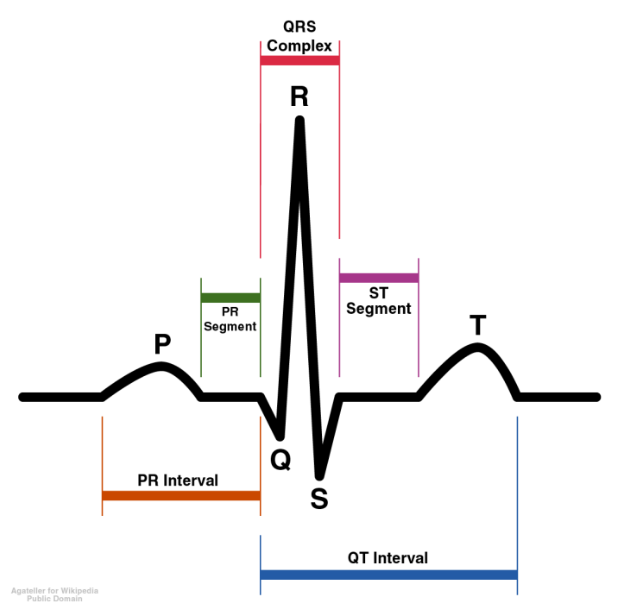

**Fig 1. Representación esquemática de un ECG normal (Anthony Atkielski).**

## Desarrollo

**Ejercicio 1: Análisis de correlación en el conjunto de datos de la flor Iris.**

- Carga el conjunto de datos de la flor Iris.

- Selecciona las cuatro variables numéricas: Longitud del sépalo (*sepal length*), Ancho del sépalo (*sepal width*), Longitud del pétalo (*petal length*) y Ancho del pétalo (*petal width*).

- Calcula la matriz de correlación entre estas variables utilizando un método adecuado (por ejemplo, el coeficiente de correlación de Pearson).

- Identifica pares de variables que presenten una correlación positiva significativa (valores cercanos a 1).

- Visualiza estas correlaciones utilizando un mapa de calor (*heatmap*) o gráficos de dispersión (*scatter plot*).

- Interpreta los resultados: **¿Qué pares de variables muestran correlación positiva fuerte? ¿Cómo podrían estas correlaciones estar relacionadas con las características de las diferentes especies de Iris?**

- Repite el análisis separando los datos por especie para ver si las correlaciones varían entre ellas.

**Ejercicio 2: Extracción de características en imágenes**

- Carga una imagen de tu elección.

- Preprocesamiento de la imagen: Convierte la imagen a escala de grises si es necesario. Aplica un filtro de suavizado (por ejemplo, un filtro Gaussiano) para reducir el ruido.

- Extracción de bordes: Utiliza el operador de *Prewitt* o *Sobel *para detectar bordes en la imagen.

- Extracción de texturas: Calcula el mapa de texturas utilizando el filtro de *Gabor* o la matriz de co-ocurrencia de niveles de gris (GLCM).

- Descriptores de forma: Utiliza la transformada de Hough para detectar líneas o círculos en la imagen. Extrae propiedades de regiones utilizando region-props.

- Visualizar y comparar los resultados:

- Visualiza los resultados de cada paso (imagen suavizada, bordes detectados, círculos detectados, etc.)

- Analiza las características extraídas (texturas, formas, bordes) y su relación con el contenido de la imagen.

**Ejercicio 3: Generación de señales sintéticas de ECG**

- Generar una señal sintética de ECG: Utilizar la función ECG de MATLAB o generar una onda sintética con sumas de senoidales. Una forma común es combinar ondas sinusoidales y pulsos para representar las ondas P, QRS y T de un ECG.

- Añadir ruido a la señal de ECG: Simular ruido de alta frecuencia (por ejemplo, ruido de 60 Hz de interferencia eléctrica) y ruido aleatorio (ruido gaussiano).

- Transformada de Fourier para analizar el espectro de frecuencia: Utilizar la Transformada Rápida de Fourier (FFT) para analizar las componentes de frecuencia de la señal con ruido.

- Diseñar un filtro en el dominio de la frecuencia: Crea un filtro pasa-bajos para eliminar el ruido de alta frecuencia (por ejemplo, frecuencias superiores a 40 Hz).

- Comparar la señal original, la señal con ruido y la señal filtrada, superponer las tres señales para observar el efecto del filtrado y comentar:

- Descripción de los pasos realizados

- Resultados obtenidos (gráficos y análisis)

- Discusión sobre la efectividad del filtrado en la eliminación del ruido

## Código

**Ejercicio 1:**

% Cargar el conjunto de datos Iris
load fisheriris

% Seleccionamos las cuatro variables numéricas
data = meas(:, 1:4);

% Calcular la matriz de correlación usando el coeficiente de Pearson
correlationMatrix = corr(data);

% Mostrar la matriz de correlación
disp('Matriz de Correlación:')

Matriz de Correlación:


disp(correlationMatrix)

    1.0000   -0.1176    0.8718    0.8179
   -0.1176    1.0000   -0.4284   -0.3661
    0.8718   -0.4284    1.0000    0.9629
    0.8179   -0.3661    0.9629    1.0000



% Identificar pares de variables con alta correlación positiva (valores cercanos a 1)
% Definimos un umbral para correlaciones fuertes
threshold = 0.75;
strongPositiveCorrelations = find(abs(correlationMatrix) > threshold & correlationMatrix ~= 1);

% Nombres de las variables numéricas
variableNames = {'Longitud sépalo', 'Ancho sépalo', 'Longitud pétalo', 'Ancho pétalo'};

% Mostrar los pares de variables con correlación positiva fuerte
disp('Pares de variables con correlación positiva fuerte:')

Pares de variables con correlación positiva fuerte:


for i = 1:length(strongPositiveCorrelations)
    [row, col] = ind2sub(size(correlationMatrix), strongPositiveCorrelations(i));
    if row < col
        fprintf('%s y %s con correlación: %.2f\n', ...
            variableNames{row}, variableNames{col}, correlationMatrix(row, col));
    end
end

Longitud sépalo y Longitud pétalo con correlación: 0.87
Longitud sépalo y Ancho pétalo con correlación: 0.82
Longitud pétalo y Ancho pétalo con correlación: 0.96


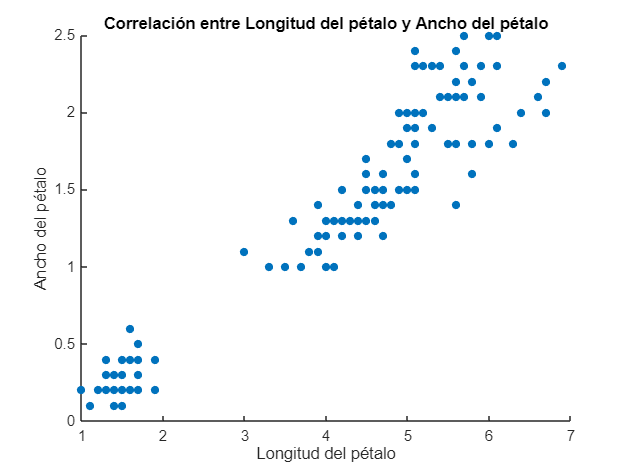

% Gráfico de dispersión para las correlaciones más fuertes
% Correlación entre Longitud del pétalo y Ancho del pétalo
figure;
scatter(data(:, 3), data(:, 4), 30, 'filled');
xlabel('Longitud del pétalo');
ylabel('Ancho del pétalo');
title('Correlación entre Longitud del pétalo y Ancho del pétalo');

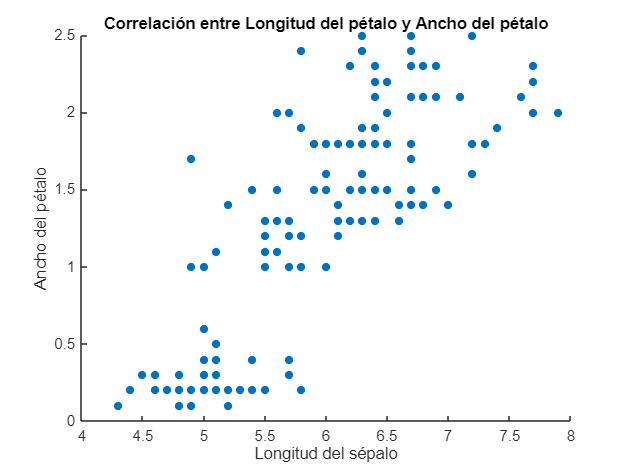

% Gráfico de dispersión para las correlaciones más fuertes
% Correlación entre Longitud del sépalo y Ancho del pétalo
figure;
scatter(data(:, 1), data(:, 4), 30, 'filled');
xlabel('Longitud del sépalo');
ylabel('Ancho del pétalo');
title('Correlación entre Longitud del pétalo y Ancho del pétalo');

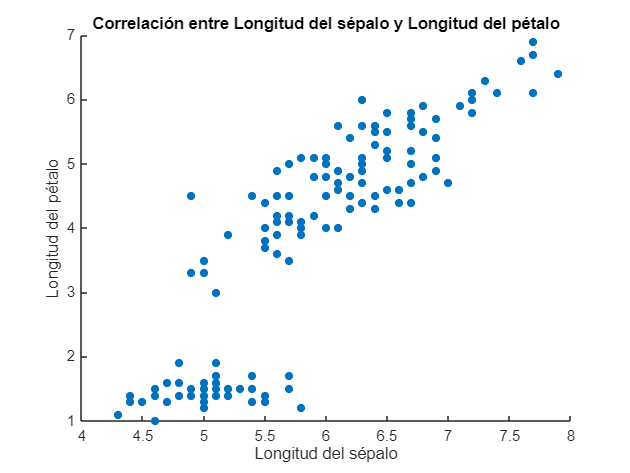

% Correlación entre Longitud del sépalo y Longitud del pétalo
figure;
scatter(data(:, 1), data(:, 3), 30, 'filled');
xlabel('Longitud del sépalo');
ylabel('Longitud del pétalo');
title('Correlación entre Longitud del sépalo y Longitud del pétalo');

**Pares de variables con correlación positiva fuerte:**

- **Longitud del sépalo y Longitud del pétalo** (correlación: 0.87)

- **Longitud del sépalo y Ancho del pétalo** (correlación: 0.82)

- **Longitud del pétalo y Ancho del pétalo** (correlación: 0.96)

**Relación con las características de las especies de Iris:**

Estas correlaciones sugieren que hay una relación lineal entre las dimensiones del sépalo y del pétalo, y pueden estar asociadas con las características morfológicas de las diferentes especies de Iris.

**Longitud del sépalo y Longitud del pétalo**:

- La correlación de 0.87 indica que, en general, las flores con sépalos más largos tienden a tener pétalos más largos.

- Esto podría reflejar que las especies de Iris con flores de mayor tamaño (más grandes tanto en sépalos como en pétalos) presentan esta tendencia. Es posible que, dentro de estas especies, la estructura de la flor esté más desarrollada, lo que podría estar relacionado con su adaptación a ciertos polinizadores o hábitats.

**Longitud del sépalo y Ancho del pétalo**:

- La correlación de 0.82 muestra que las especies de Iris con sépalos largos también tienden a tener pétalos más anchos.

- Este comportamiento podría reflejar una simetría en el tamaño de las partes florales, donde las flores más grandes no solo tienen sépalos más largos, sino que también los pétalos son proporcionalmente más anchos.

**Longitud del pétalo y Ancho del pétalo**:

- La correlación de 0.96 es muy fuerte, lo que indica que las flores con pétalos más largos también tienden a tener pétalos más anchos.

- Esto es lógico, ya que generalmente las flores con pétalos largos suelen tener una estructura más amplia para proporcionar suficiente espacio para la atracción de polinizadores. Esta correlación también sugiere que, en ciertas especies, el tamaño y la forma de los pétalos están estrechamente relacionados entre sí, lo que podría ser una característica evolutiva para atraer mejor a los polinizadores.

% Inicializamos una celda para almacenar las matrices de correlación por especie
correlationMatrices = cell(3,1);

% Nombres de las especies
uniqueSpecies = unique(species);

% Calcular la matriz de correlación para cada especie
for i = 1:length(uniqueSpecies)
    % Seleccionar los datos de la especie actual
    speciesData = data(strcmp(species, uniqueSpecies{i}), :);
    
    % Calcular la matriz de correlación para la especie actual
    correlationMatrix = corr(speciesData);
    correlationMatrices{i} = correlationMatrix;
    
    % Mostrar la matriz de correlación para la especie
    disp(['Matriz de correlación para ', uniqueSpecies{i}, ':'])
    disp(correlationMatrix)
    
    % Identificar pares de variables con alta correlación positiva (valores cercanos a 1)
    threshold = 0.75;
    strongPositiveCorrelations = find(abs(correlationMatrix) > threshold & correlationMatrix ~= 1);
    
    % Mostrar los pares de variables con correlación positiva fuerte
    disp(['Pares de variables con correlación positiva fuerte para ', uniqueSpecies{i}, ':'])
    for j = 1:length(strongPositiveCorrelations)
        [row, col] = ind2sub(size(correlationMatrix), strongPositiveCorrelations(j));
        if row < col % Solo mostrar la mitad superior de la matriz
            fprintf('%s y %s con correlación: %.2f\n', ...
                'Longitud sépalo', 'Longitud pétalo', correlationMatrix(1, 3)); % Ejemplo de una impresión correcta
        end
    end
end

Matriz de correlación para setosa:


    1.0000    0.7425    0.2672    0.2781
    0.7425    1.0000    0.1777    0.2328
    0.2672    0.1777    1.0000    0.3316
    0.2781    0.2328    0.3316    1.0000



Pares de variables con correlación positiva fuerte para setosa:


Matriz de correlación para versicolor:


    1.0000    0.5259    0.7540    0.5465
    0.5259    1.0000    0.5605    0.6640
    0.7540    0.5605    1.0000    0.7867
    0.5465    0.6640    0.7867    1.0000



Pares de variables con correlación positiva fuerte para versicolor:


Longitud sépalo y Longitud pétalo con correlación: 0.75
Longitud sépalo y Longitud pétalo con correlación: 0.75


Matriz de correlación para virginica:


    1.0000    0.4572    0.8642    0.2811
    0.4572    1.0000    0.4010    0.5377
    0.8642    0.4010    1.0000    0.3221
    0.2811    0.5377    0.3221    1.0000



Pares de variables con correlación positiva fuerte para virginica:


Longitud sépalo y Longitud pétalo con correlación: 0.86


- **Setosa**: La falta de correlaciones fuertes podría reflejar una mayor variabilidad en las proporciones de los sépalos y los pétalos, lo que podría estar relacionado con adaptaciones específicas o una mayor diversidad dentro de las flores de esta especie.

- **Versicolor**: Aunque hay dos correlaciones positivas entre la longitud del sépalo y la longitud del pétalo, no son tan fuertes como en Virginica, lo que podría indicar una menor consistencia en la relación entre estas características.

- **Virginica**: La correlación fuerte entre la longitud del sépalo y la longitud del pétalo podría indicar una mayor especialización en las dimensiones florales y una relación proporcional más estrecha entre estos dos factores en esta especie.

**Ejercicio 2:**

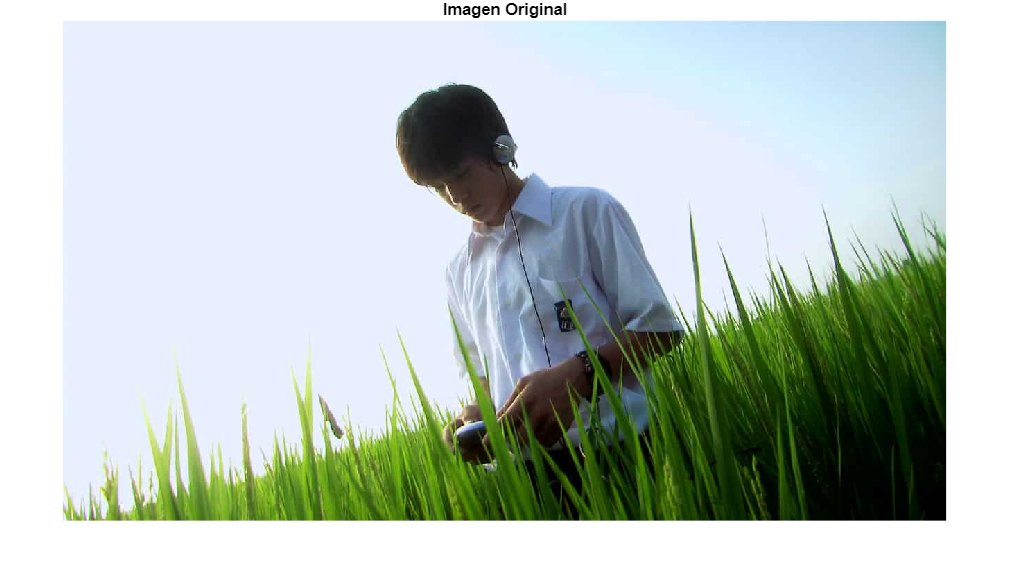

% Cargar la imagen
img = imread("lily.jpg");

% Mostrar imagen original
figure;
imshow(img);
title('Imagen Original');

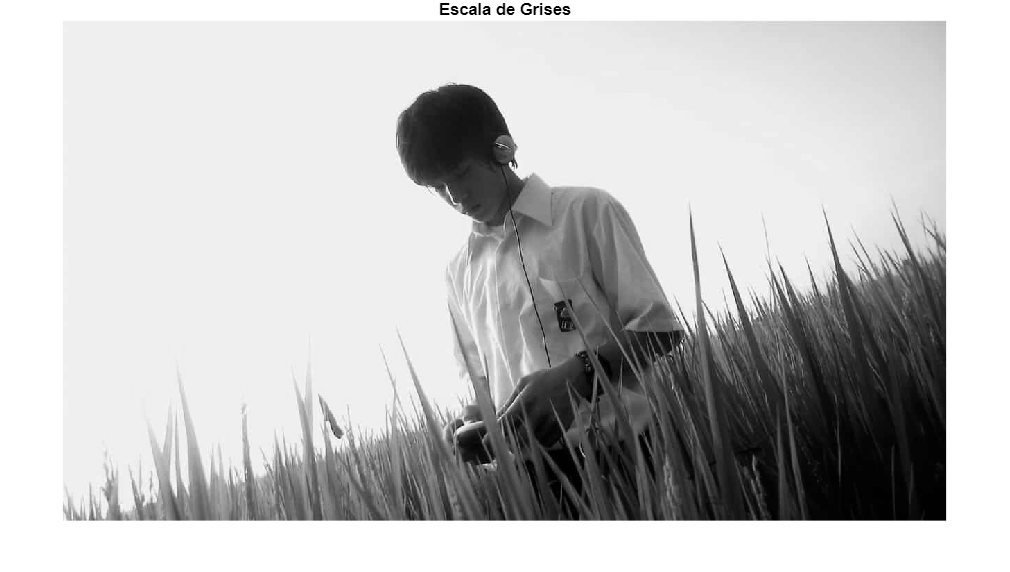

% Preprocesamiento de la imagen
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
img_gray = rgb2gray(img);

% Mostrar imagen en escala de grises
figure;
imshow(img_gray);
title('Escala de Grises');

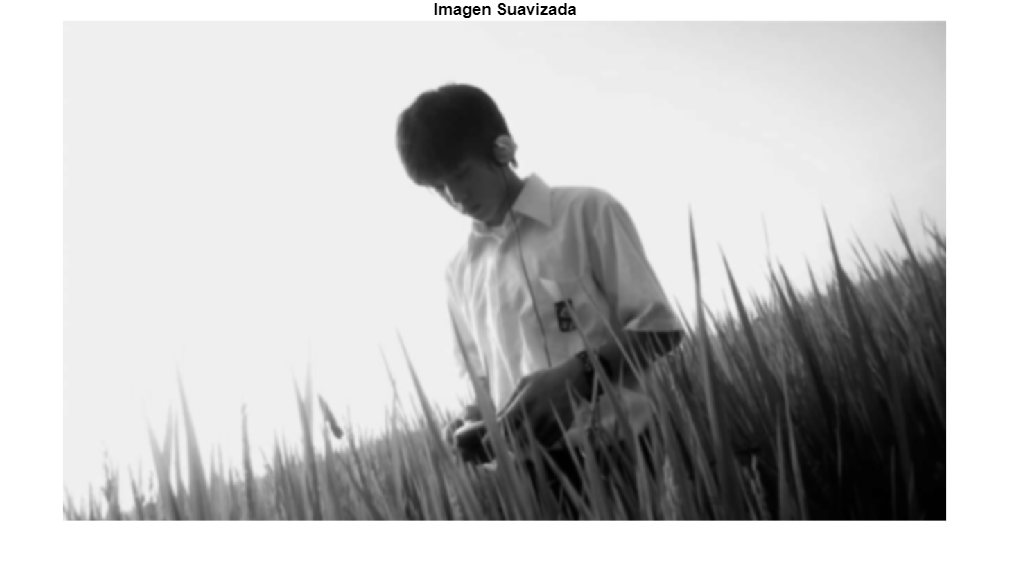

% Aplicar filtro Gaussiano para suavizado
img_smooth = imgaussfilt(img_gray, 2);
% Mostrar imagen suavizada
figure;
imshow(img_smooth);
title('Imagen Suavizada');

**Pasos realizados**

- Se transformó la imagen a escala de grises.

- Se aplicó un filtro gaussiano para suavizar la imagen. Con ayuda de un slider se ajustó el parámetro sigma de manera que la deteccion de bordes sea mas adecuada visualmente.

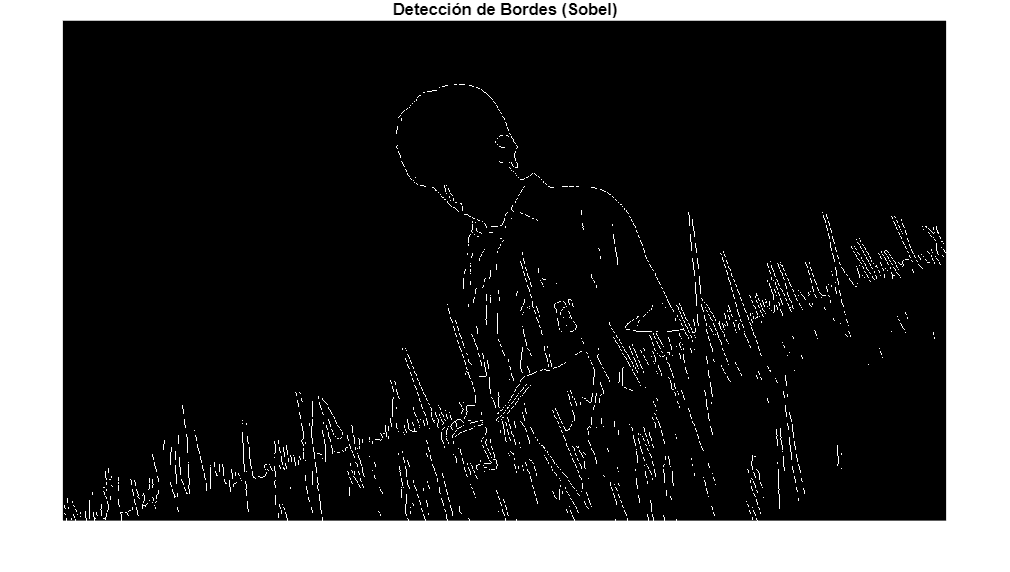

% Extracción de bordes
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Detección de bordes usando el operador de Sobel
edges = edge(img_smooth);

% Mostrar la imagen con bordes detectados
figure;
imshow(edges);
title('Detección de Bordes (Sobel)');

**Pasos realizados**

- Se aplico la funcion de Sobel para extrar los bordes de la figura.

**Analisis de caracteristicas extraidas**

- Los bordes delimitan de manera suficiente la figura de la persona pero con un poco de dificultades en el area de la camisa, quizas por el fondo claro. La parte alta del pasto esta bien delimitada, pero los bordes entre las hojas no estan tan definidas.

% Extracción de texturas:
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Calcular la matriz de co-ocurrencia (GLCM)
glcm = graycomatrix(img_gray); 

% Extraer propiedades de textura
stats = graycoprops(glcm, {'Contrast', 'Correlation', 'Energy', 'Homogeneity'});

% Mostrar propiedades de textura
disp('Propiedades de textura (GLCM):');

Propiedades de textura (GLCM):


disp(stats);

       Contrast: 0.1270
    Correlation: 0.9907
         Energy: 0.3331
    Homogeneity: 0.9531



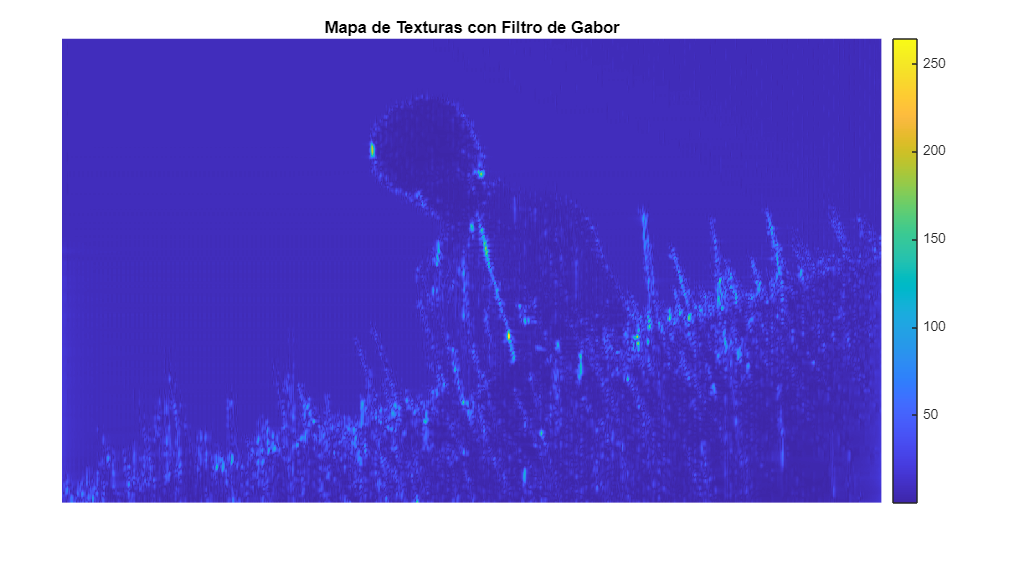

% Definir los parámetros del filtro de Gabor
lambda =2;    % Longitud de onda
theta = 0;    % Orientación en radianes (0 grados)

% Crear el filtro de Gabor
gaborFilter = gabor(lambda, theta);

% Aplicar el filtro de Gabor
gaborMag = imgaborfilt(img_gray, gaborFilter);

% Mostrar el mapa de texturas
figure;
imshow(gaborMag, []);
colormap parula;
colorbar;
title('Mapa de Texturas con Filtro de Gabor');

**Pasos realizados**

- Se obtuvieron las caracteristicas de textura con la matriz de co-ocurrencia (GLCM)

- Se aplico un filtro de Gabor a la imagen para generar el mapa de texturas. Con ayuda de un slider se vario el parametro de la longitud de onda hasta encontrar un valor adecuado (a mi percepcion).

**Analisis de caracteristicas extraidas**

- La imagen es mayormente homogenea y suave (alta homogeneidad y bajo contraste).

- La imagen tiene patrones repetitivos (alta correlacion y energia)

- Lo anterior es facilmente explicable por la gran cantidad de pasto y la gran proporcion de cielo que se muestra en la imagen.

- El mapa de texturas muestra como el cielo tiene todo el mismo patron. La diferencia entre la textura del pasto y el chico de la foto es bastante notable. Es posible tambien ver una diferencia entre la textura de la camisa y la de la cabeza del chico.

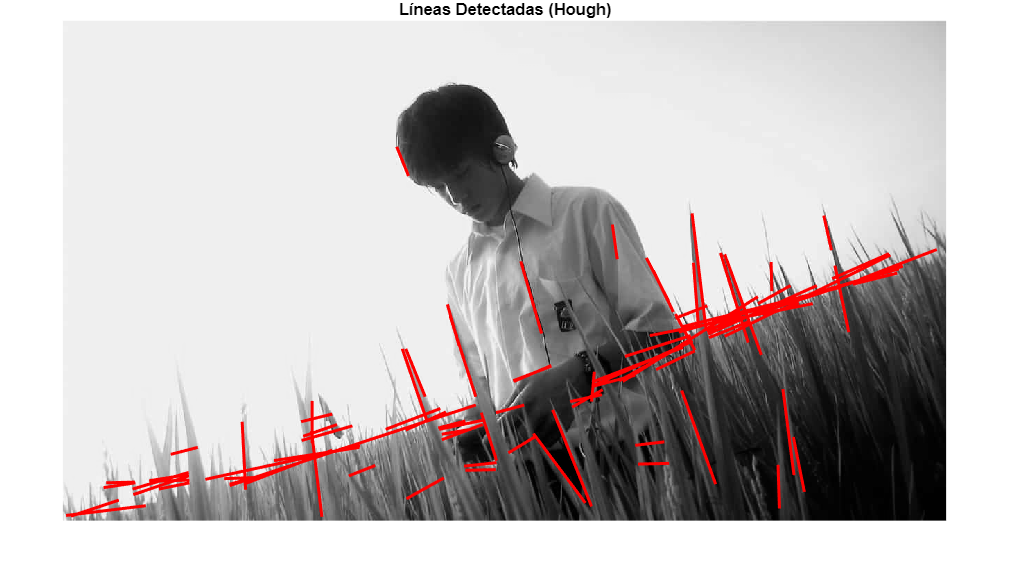

% Descriptores de forma
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Transformada de Hough para detección de líneas
[H, theta, rho] = hough(edges);
peaks = houghpeaks(H, 95);
lines = houghlines(edges, theta, rho, peaks);

% Mostrar la imagen con líneas detectadas
figure;
imshow(img_gray); hold on;
for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];
    plot(xy(:,1), xy(:,2), 'LineWidth', 2, 'Color', 'red');
end
title('Líneas Detectadas (Hough)'); 
hold off;

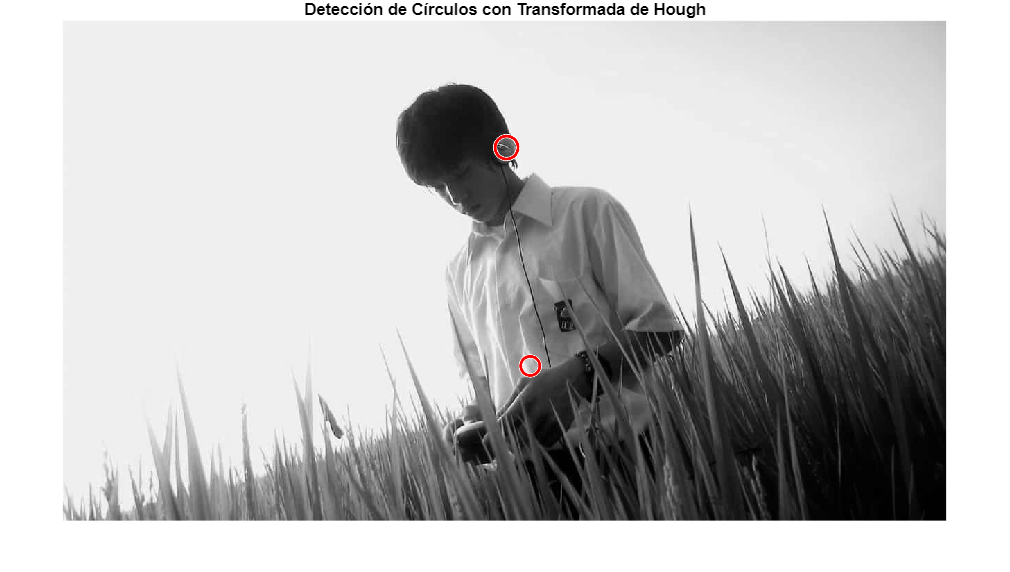

% Aplicar la Transformada de Hough para detectar círculos
[centers, radii] = imfindcircles(img_smooth, [10 100], 'Sensitivity', 0.68, 'EdgeThreshold', 0.06);

% Mostrar la imagen original con los círculos detectados
figure;
imshow(img_gray);
hold on;

% Dibujar los círculos detectados
viscircles(centers, radii, 'EdgeColor', 'r');

title('Detección de Círculos con Transformada de Hough');
hold off;

**Pasos realizados**

- De los bordes obtenidos anteriormente, se utilizo la transformada de Hough para detectar líneas.

- Con ayuda de un slider ajustamos el parametro para mostrar el numero maximo de picos que se detectan en la imagen.

**Analisis de caracteristicas extraidas**

- La mayor parte de las lineas que se encontraron fueron en el pasto. Hay algunas lineas horizontales en la division entre el pasto y el cielo que estan bien marcadas, pero hay otras que no aparecen en la imagen original. Se encontraron lineas en la camisa, en el cable y en la cabeza que estan bien definidas. Quizas faltaron algunas mas como el cuello de la camisa y el hombro del chico.

- En el caso de los circulos, la imagen tiene (a simple vista) un solo circulo bien definido, en los audifonos del chico. Sin embargo, despues de ajustar los valores del threshold y la sensibilidad, se encontro un circulo que, a simple vista no existe en la imagen original.

**Ejercicio 3:**

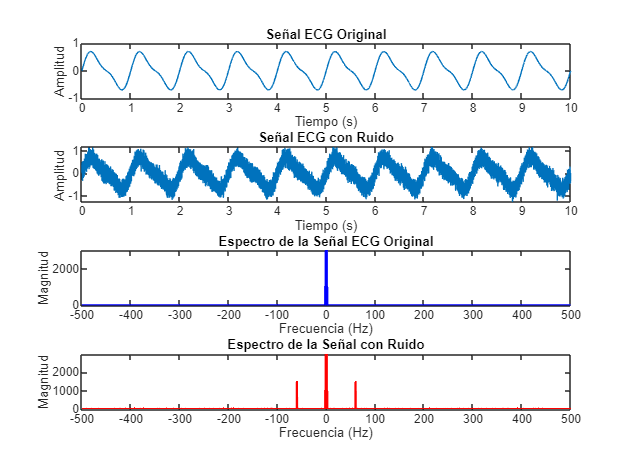

% Parámetros de la señal ECG
fs = 1000;               % Frecuencia de muestreo (Hz)
t = 0:1/fs:10;           % Tiempo de 10 segundos
f_rpeaks = 1.0;          % Frecuencia de los picos R del ECG (1 Hz aproximadamente)
f_pqrs = 2;              % Frecuencia de las ondas P, QRS, T (aproximación para señales)

% Generación de la señal sintética de ECG (sumando sinusoides)
ecg = 0.6 * sin(2*pi*f_rpeaks*t) + 0.2 * sin(2*pi*f_pqrs*t);

% Añadir ruido a la señal (ruido de interferencia eléctrica de 60 Hz y ruido gaussiano)
noise_60hz = 0.3 * sin(2*pi*60*t);       % Ruido de 60 Hz (interferencia eléctrica)
noise_gaussian = 0.1 * randn(size(t));   % Ruido gaussiano aleatorio
noisy_ecg = ecg + noise_60hz + noise_gaussian;

% Visualizar la señal original y la señal con ruido
figure;
subplot(4,1,1);
plot(t, ecg);
title('Señal ECG Original');
xlabel('Tiempo (s)');
ylabel('Amplitud');

subplot(4,1,2);
plot(t, noisy_ecg);
title('Señal ECG con Ruido');
xlabel('Tiempo (s)');
ylabel('Amplitud');

% Transformada Rápida de Fourier (FFT) para analizar el espectro de frecuencia
N = length(t);
f = (-N/2:N/2-1)*(fs/N);  % Ejes de frecuencia
ecg_fft = fftshift(fft(ecg));  % FFT de la señal original
noisy_ecg_fft = fftshift(fft(noisy_ecg));  % FFT de la señal con ruido

% Visualizar el espectro de la señal original
subplot(4,1,3);
plot(f, abs(ecg_fft), 'b', 'LineWidth', 1.5);
% plot(f, abs(noisy_ecg_fft), 'r', 'LineWidth', 1.5);
title('Espectro de la Señal ECG Original');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');

% Visualizar el espectro de la señal con ruido
subplot(4,1,4);
plot(f, abs(noisy_ecg_fft), 'r', 'LineWidth', 1.5);
title('Espectro de la Señal con Ruido');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');

**Pasos realizados**

- Usamos dos ondas seno (una para la onda P/QRS/T y otra para los picos R) para aproximar la señal ECG (f_rpeaks y f_pqrs Hz son frecuencias aproximadas para la generación de la señal).

- Simulamos interferencia de ruido eléctrico de 60 Hz y añadimos ruido aleatorio para simular interferencias adicionales.

- Calculamos la FFT de la señal original y la señal con ruido para observar las componentes de frecuencia.

**Analisis de las graficas**

- Vemos el espectro de frecuencias de la señal original y la señal con ruido, donde se nota la presencia de picos adicionales en 60 Hz debido al ruido.

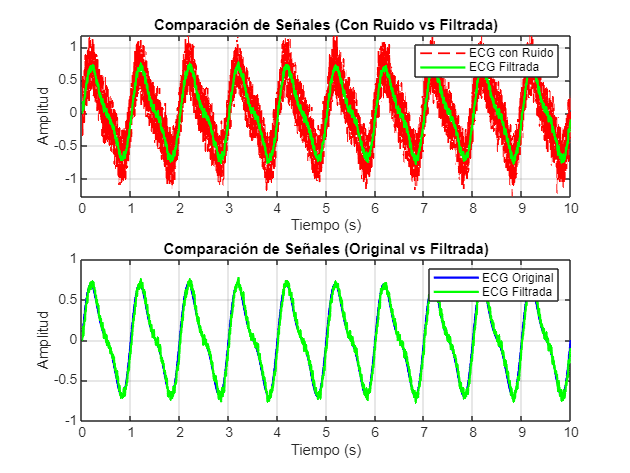

% Filtro pasa-bajos (40 Hz de corte)
cutoff_frequency = 40;  % Frecuencia de corte del filtro pasa-bajos (Hz)
[b, a] = butter(6, cutoff_frequency / (fs/2), 'low');  % Filtro Butterworth de 6° orden

% Aplicar el filtro pasa-bajos
filtered_ecg = filter(b, a, noisy_ecg);

% Nueva figura para la comparación de señales
figure;
subplot(2,1,1);
plot(t, noisy_ecg, 'r--', 'LineWidth', 1.2);
hold on;
plot(t, filtered_ecg, 'g', 'LineWidth', 1.5);
title('Comparación de Señales (Con Ruido vs Filtrada)');
xlabel('Tiempo (s)');
ylabel('Amplitud');
legend('ECG con Ruido', 'ECG Filtrada');
grid on;

% Subplot 5: Señal original vs filtrada
subplot(2,1,2);
plot(t, ecg, 'b', 'LineWidth', 1.5);
hold on;
plot(t, filtered_ecg, 'g', 'LineWidth', 1.5);
title('Comparación de Señales (Original vs Filtrada)');
xlabel('Tiempo (s)');
ylabel('Amplitud');
legend('ECG Original', 'ECG Filtrada');
grid on;

**Pasos realizados**

- Usamos un filtro Butterworth de 6º orden con una frecuencia de corte de 40 Hz para eliminar el ruido de alta frecuencia.

- Aplicamos este filtro a la señal con ruido para obtener la señal filtrada.

**Analisis de la grafica**

- Vemos como la señal filtrada reduce el ruido de alta frecuencia, y de esta manera, se compara razonablemente bien con la señal original.

## Conclusiones

En esta práctica, se exploraron distintas técnicas para el análisis y procesamiento de datos en el contexto del reconocimiento de patrones, aplicando herramientas de MATLAB en tres dominios principales: análisis de correlaciones en conjuntos de datos, procesamiento de imágenes, asi como procesamiento de señales fisiológicas y filtrado.

**1. Análisis de correlaciones en el dataset de Iris**

Se evaluaron las correlaciones entre las características de las flores del dataset Iris para identificar relaciones entre variables como la longitud y el ancho de los sépalos y pétalos. Los resultados mostraron que existen correlaciones significativas entre algunas variables, como la relación entre la longitud del sépalo y la longitud del pétalo, lo que sugiere que estas medidas pueden ser indicativas de la clasificación de especies. Al segmentar por especie, se observó que la correlación varía dependiendo de la clase, lo que demuestra que la estructura interna de los datos es diferente para cada tipo de flor.

Este análisis es clave en Reconocimiento de Patrones, ya que ayuda a entender cómo se distribuyen los datos y qué características pueden ser más relevantes para la clasificación.

**2. Procesamiento de imagenes**

Aplicamos diversas técnicas de procesamiento de imágenes para extraer información relevante. La combinación de estas técnicas demostró funcionar de manera general, sin embargo, pueden obtenerse mejores resultados al variar los parametros y experimentar con las diferentes herramientas de procesamiento. La detección de bordes, la extracción de texturas y la detección de formas permiten segmentar e interpretar imágenes de manera estructurada, facilitando su uso en aplicaciones de visión por computadora.

**3. Procesamiento y filtrado de senales**

Se generó una señal sintética de ECG con ondas sinusoidales representando las principales características del ciclo cardiaco. Posteriormente, se le agregó ruido de 60 Hz y ruido gaussiano aleatorio para simular condiciones reales. Aplicando la Transformada Rápida de Fourier (FFT), se analizó el espectro de frecuencia, evidenciando la presencia de ruido en altas frecuencias. Finalmente, se diseñó un filtro pasa-bajos (40 Hz) con el objetivo de eliminar el ruido sin distorsionar la señal original.

Este ejercicio resalta la importancia de la eliminación de ruido y preprocesamiento de datos, pasos fundamentales en el reconocimiento de patrones en señales fisiológicas, como la detección de arritmias o eventos cardiacos anómalos.

Dicho lo anterior podemos sugerir que se cumplieron los objetivos planteados para la realizacion de esta practica.

## Referencias

- Gonzalez, R., Woods, R., Digital Image Processing, Prentice Hall, 2008.

- Pratt, W. k., Digital Image Processing, John Wiley and Sons Inc, 2001.

- Jahne, B., Digital Image Processing, Springer, 2005.

- Sánchez Garreta, Josep Salvador; García, Vicente. Special Issue on Data Preprocessing in Pattern Recognition: Recent Progress, Trends and Applications. 2022.

- Majidi, Mehrdad; Oskuoee, Mohammad. Improving pattern recognition accuracy of partial discharges by new data preprocessing methods. Electric Power Systems Research, 2015, vol. 119, p. 100-110.

- Lotfi, Safia, et al. Recent progress on the synthesis, morphology and photocatalytic dye degradation of BiVO4 photocatalysts: A review. Catalysis Reviews, 2024, vol. 66, no 1, p. 214-258.